# Equation of Motion through the Lagrange Approach

## Analysis of the mechanism

The mechanism has 2 d.o.f. in space namely identified as: $\theta \left(t\right),\alpha \left(t\right)$.

Here we introduce some symbolic variables representing the parameters involved in the grey-box model of the system.

**Remark: **Most likely, it will be a system of order 2.

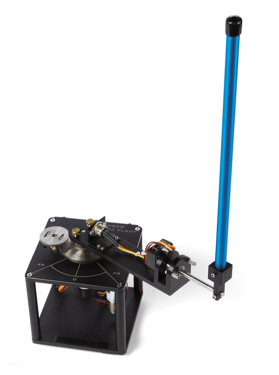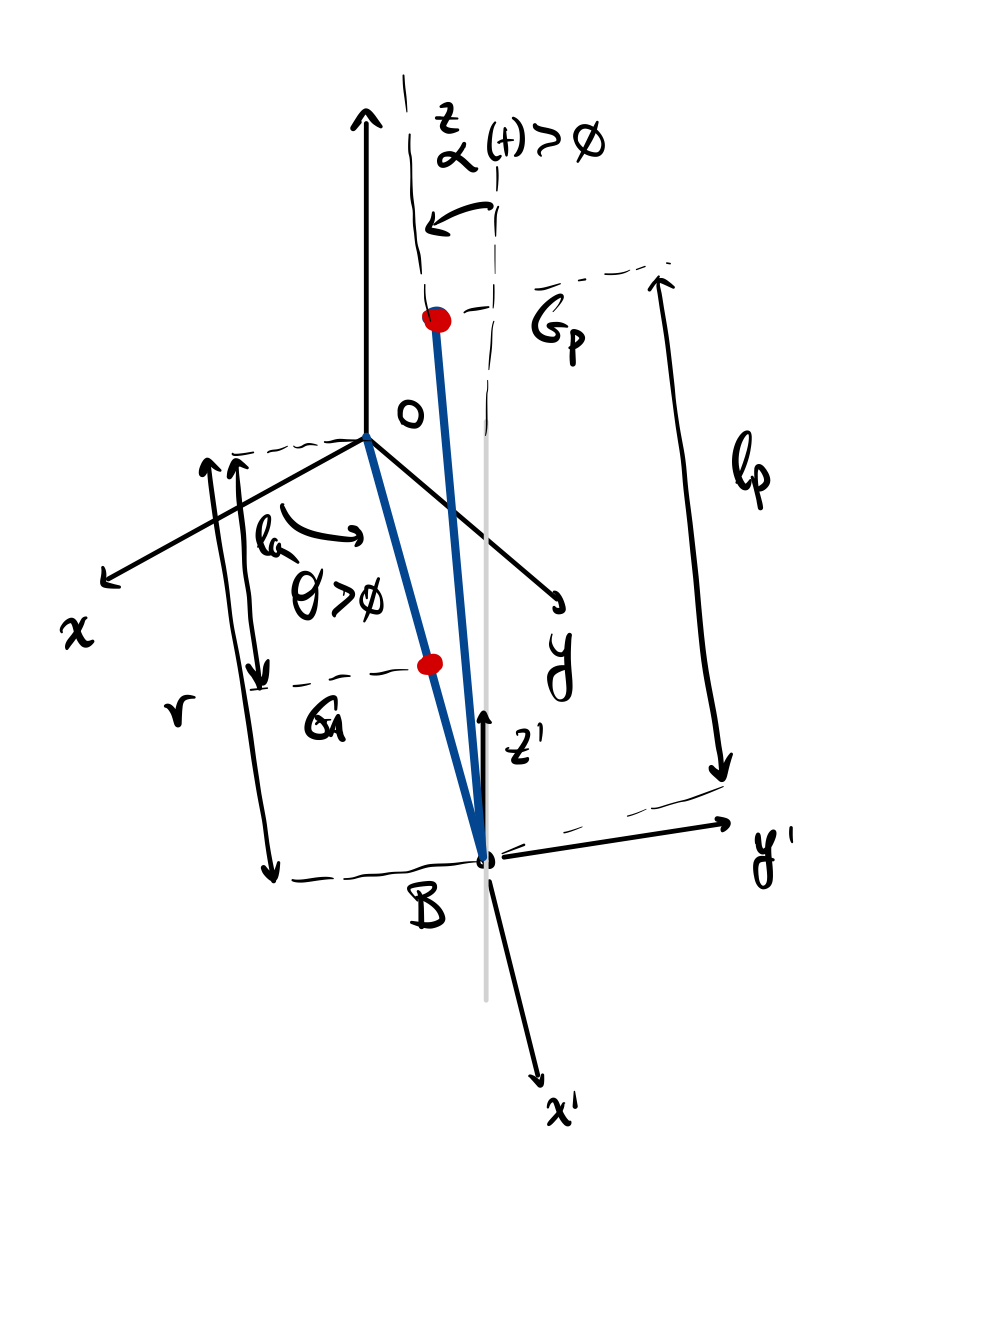

clear
syms t ...      % time variable
    theta(t)... % angle of horizontal arm
    alpha(t)... % angle of vertical arm wrt vertical upright direction
    alpha_dot theta_dot alpha_ddot theta_ddot...
    alpha_t theta_t ... % indep. coordinates and their derivatives
    x_Ga(t) y_Ga(t) z_Ga(t) x_B(t) y_B(t) z_B(t)... % coordinates of notable points horizontal arm
    m_a... % mass of the horizontal arm
    J_a... % moment of inertia of horizontal arm wrt 'O'
    l_a... % position of the center of mass with respect to 'O'
    r  ... % total length of horizontal arm
    x_Gp(t) y_Gp(t) z_Gp(t)... % C.O.M. vertical arm wrt inertial frame
    m_p... % mass of vertical arm
    J_p... % moment of inertia wrt the C.o.M. of the vertical arm
    l_p ...% position of C.o.M. along the vertical arm
    g...   % gravitational acceleration
    tau... % motor torque
    B_r... % Rotary arm viscous damping coefficient as seen at the pivot axis ('O')
    B_p... % Pendulum viscous damping coefficient as seen at the pivot axis ('O')
    x_1 x_2 x_3 x_4... % state space variables
    x_dot_1 x_dot_2 x_dot_3 x_dot_4... % state derivatives
    J_T ...   % determinant of D(q) accelerations matrix
    eta_g ... % gearbox efficiency
    eta_m...  % motor effieciency
    K_g...    % gear ratio in high gear config
    k_t...    % motor current-torque constant
    V_m...    % input voltage
    k_m...    % motor-back emf constant
    R_m    % armature resistance

For the all possible values of the parameters that we found in the literature check [this link](https://www.notion.so/System-Physical-Parameters-Values-from-literature-796efa849a1a48a3a09d2c81c7839a15?pvs=4).

## Position Analysis

First we identify the position of some notable points in the mechanism such as:

- centers of mass of both arm 

- position of the non actuated joint

with respect to an inertial reference frame centered at hinge 'O' where the motor axis is attached to the horizontal arm.

### Position of $G_A$:

pos_Ga = [x_Ga(t);y_Ga(t);z_Ga(t)] == [l_a*cos(theta); l_a*sin(theta); 0]

$$pos\_Ga(t) = \left(\begin{array}{c} x_{\mathrm{Ga}}\left(t\right)=l_{a}\,\cos\left(\theta \left(t\right)\right)\\ y_{\mathrm{Ga}}\left(t\right)=l_{a}\,\sin\left(\theta \left(t\right)\right)\\ z_{\mathrm{Ga}}\left(t\right)=0 \end{array}\right)$$

pos_B = [x_B(t);y_B(t);z_B(t)] == [r*cos(theta); r*sin(theta(t)); 0]

$$pos\_B(t) = \left(\begin{array}{c} x_{B}\left(t\right)=r\,\cos\left(\theta \left(t\right)\right)\\ y_{B}\left(t\right)=r\,\sin\left(\theta \left(t\right)\right)\\ z_{B}\left(t\right)=0 \end{array}\right)$$

Rotation matrix linking inertial frame to frame attached to horizontal harm. The columns of this matrix are represented by the components of the versors of arm frame in the inertial frame.

R = [cos(theta) -sin(theta)  0;
     sin(theta)  cos(theta)  0;
         0           0       1]

$$R(t) = \left(\begin{array}{ccc} \cos\left(\theta \left(t\right)\right) & -\sin\left(\theta \left(t\right)\right) & 0\\ \sin\left(\theta \left(t\right)\right) & \cos\left(\theta \left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

### Position of $G_P$:

pos_Gp = [x_Gp(t);y_Gp(t);z_Gp(t)] == rhs(pos_B) + R*[0; -l_p*sin(alpha(t));l_p*cos(alpha(t))]

$$pos\_Gp(t) = \left(\begin{array}{c} x_{\mathrm{Gp}}\left(t\right)=r\,\cos\left(\theta \left(t\right)\right)+l_{p}\,\sin\left(\alpha \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\\ y_{\mathrm{Gp}}\left(t\right)=r\,\sin\left(\theta \left(t\right)\right)-l_{p}\,\sin\left(\alpha \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\\ z_{\mathrm{Gp}}\left(t\right)=l_{p}\,\cos\left(\alpha \left(t\right)\right) \end{array}\right)$$

## Lagrange Approach to find the equations of motion

### Kinetic Energy

#### Body 1

Having the moment of inertia with respect to the pivot, we can consider only the rotational dynamic of the horizontal arm.

T1 = (1/2)*(J_a*(diff(theta,t))^2) % rotational velocity of body 1

$$T1(t) = \frac{J_{a}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}$$

#### Body 2

First we compute the velocity vector of the $G_P$ in the inertial frame 

v_Gp = diff(rhs(pos_Gp),t)

$$v\_Gp(t) = \left(\begin{array}{c} l_{p}\,\cos\left(\alpha \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)-r\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+l_{p}\,\sin\left(\alpha \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ r\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+l_{p}\,\sin\left(\alpha \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-l_{p}\,\cos\left(\alpha \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)\\ -l_{p}\,\sin\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\alpha \left(t\right) \end{array}\right)$$

vel = v_Gp(t)

$$vel = \left(\begin{array}{c} l_{p}\,\cos\left(\alpha \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)-r\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+l_{p}\,\sin\left(\alpha \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ r\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+l_{p}\,\sin\left(\alpha \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-l_{p}\,\cos\left(\alpha \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)\\ -l_{p}\,\sin\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\alpha \left(t\right) \end{array}\right)$$

Then we can compute the Kinetic energy of the body following **Konig Theorem**

T2 = (1/2)*(m_p*(vel(1)^2 + vel(2)^2 + vel(3)^2) + J_p*diff(alpha,t)^2)

$$T2(t) = \begin{array}{l} \frac{m_{p}\,\left({\left(r\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+l_{p}\,\sin\left(\alpha \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-l_{p}\,\cos\left(\alpha \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)\right)}^{2}+{\left(-r\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+l_{p}\,\cos\left(\alpha \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)+l_{p}\,\sin\left(\alpha \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+{l_{p}}^{2}\,{\sin\left(\alpha \left(t\right)\right)}^{2}\,\sigma_{1}\right)}{2}+\frac{J_{p}\,\sigma_{1}}{2}\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\alpha \left(t\right)\right)}^{2} \end{array}$$

#### Total Kinetic Energy of the system

The Kinetic Energy is an additive quantity, thus we obtain the total kinetic energy of the system by summing the Kinetic energies of the single bodies.

T_tot = T1 + T2

$$T\_tot(t) = \begin{array}{l} \frac{m_{p}\,\left({\left(r\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+l_{p}\,\sin\left(\alpha \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-l_{p}\,\cos\left(\alpha \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)\right)}^{2}+{\left(-r\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+l_{p}\,\cos\left(\alpha \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)+l_{p}\,\sin\left(\alpha \left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+{l_{p}}^{2}\,{\sin\left(\alpha \left(t\right)\right)}^{2}\,\sigma_{1}\right)}{2}+\frac{J_{p}\,\sigma_{1}}{2}+\frac{J_{a}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\alpha \left(t\right)\right)}^{2} \end{array}$$

## Potential Energy

We consider the effect of the gravitational force on the vertical arm thus compute the potential energy, whose 0 value is set at the unstable configuration of the system.

V = m_p*g*l_p*(cos(alpha)-1)

$$V(t) = g\,l_{p}\,m_{p}\,\left(\cos\left(\alpha \left(t\right)\right)-1\right)$$

## Generalized Forces

Here we consider the generalized forces acting on the 2 generalized coordinates.

**Remark: **We are already considering the term $\frac{\textrm{d}}{\textrm{d}\dot{q} }D$ on the right handside with the generalized forces acting on the 2 d.o.f.

Q1 = tau-B_r*theta_dot;
Q2 = -B_p*alpha_dot;

## Lagrangian

We define the Lagrange function

L = T_tot - V;

## Lagrange Equations

And from the Lagrangian we derive the lagrange equations:

eqn1 = diff(diff(L,diff(theta,t)),t) - diff(L,theta) == Q1;
eqn2 = diff(diff(L,diff(alpha,t)),t) - diff(L,alpha) == Q2;
eqn1 = simplify(eqn1);
eqn2 = simplify(eqn2);
eqn1 = simplify(collect(eqn1,[diff(theta,t,2),diff(theta,t),theta,diff(alpha,t,2),diff(alpha,t),alpha]));
eqn2 = simplify(collect(eqn2,[diff(theta,t,2),diff(theta,t),theta,diff(alpha,t,2),diff(alpha,t),alpha]));

### Obtaining the Non Linear Equations

Removing symbolic time dependence:

eqn1 = simplify(subs(eqn1,[diff(theta,t,2),diff(theta,t),theta(t) ,diff(alpha,t,2),diff(alpha,t),alpha(t)],[theta_ddot, theta_dot, theta_t, alpha_ddot, alpha_dot, alpha_t]))

$$eqn1(t) = m_{p}\,\ddot{\theta }\,{l_{p}}^{2}\,{\cos\left(\alpha_{t}\right)}^{2}+\ddot{\alpha }\,m_{p}\,r\,l_{p}\,\cos\left(\alpha_{t}\right)+\tau =B_{r}\,\dot{\theta }+\ddot{\theta }\,\left(m_{p}\,{l_{p}}^{2}+m_{p}\,r^{2}+J_{a}\right)+{\dot{\alpha }}^{2}\,l_{p}\,m_{p}\,r\,\sin\left(\alpha_{t}\right)+\dot{\alpha }\,{l_{p}}^{2}\,m_{p}\,\dot{\theta }\,\sin\left(2\,\alpha_{t}\right)$$

eqn2 = simplify(subs(eqn2,[diff(theta,t,2),diff(theta,t),theta(t) ,diff(alpha,t,2),diff(alpha,t),alpha(t)],[theta_ddot, theta_dot, theta_t, alpha_ddot, alpha_dot, alpha_t]))

$$eqn2(t) = 2\,B_{p}\,\dot{\alpha }+2\,\ddot{\alpha }\,\left(m_{p}\,{l_{p}}^{2}+J_{p}\right)=2\,g\,l_{p}\,m_{p}\,\sin\left(\alpha_{t}\right)+{l_{p}}^{2}\,m_{p}\,{\dot{\theta }}^{2}\,\sin\left(2\,\alpha_{t}\right)+2\,l_{p}\,m_{p}\,r\,\ddot{\theta }\,\cos\left(\alpha_{t}\right)$$

Isolating the generalized forces on the right hand-side of the equations:

eqn1 = rhs(eqn1)-lhs(eqn1) + Q1 + B_r*theta_dot == Q1 + B_r*theta_dot

$$eqn1(t) = B_{r}\,\dot{\theta }+\ddot{\theta }\,\left(m_{p}\,{l_{p}}^{2}+m_{p}\,r^{2}+J_{a}\right)-{l_{p}}^{2}\,m_{p}\,\ddot{\theta }\,{\cos\left(\alpha_{t}\right)}^{2}+{\dot{\alpha }}^{2}\,l_{p}\,m_{p}\,r\,\sin\left(\alpha_{t}\right)+\dot{\alpha }\,{l_{p}}^{2}\,m_{p}\,\dot{\theta }\,\sin\left(2\,\alpha_{t}\right)-\ddot{\alpha }\,l_{p}\,m_{p}\,r\,\cos\left(\alpha_{t}\right)=\tau$$

eqn2 = lhs(eqn2)-rhs(eqn2)== 0

$$eqn2(t) = 2\,B_{p}\,\dot{\alpha }+2\,\ddot{\alpha }\,\left(m_{p}\,{l_{p}}^{2}+J_{p}\right)-2\,g\,l_{p}\,m_{p}\,\sin\left(\alpha_{t}\right)-{l_{p}}^{2}\,m_{p}\,{\dot{\theta }}^{2}\,\sin\left(2\,\alpha_{t}\right)-2\,l_{p}\,m_{p}\,r\,\ddot{\theta }\,\cos\left(\alpha_{t}\right)=0$$

eqn1 = collect(eqn1,[theta_ddot, theta_dot,theta_t, alpha_ddot, alpha_dot,alpha_t])

$$eqn1(t) = \left(-m_{p}\,{l_{p}}^{2}\,{\cos\left(\alpha_{t}\right)}^{2}+m_{p}\,{l_{p}}^{2}+m_{p}\,r^{2}+J_{a}\right)\,\ddot{\theta }+\left({l_{p}}^{2}\,m_{p}\,\sin\left(2\,\alpha_{t}\right)\right)\,\dot{\theta }\,\dot{\alpha }+B_{r}\,\dot{\theta }+\left(-l_{p}\,m_{p}\,r\,\cos\left(\alpha_{t}\right)\right)\,\ddot{\alpha }+\left(l_{p}\,m_{p}\,r\,\sin\left(\alpha_{t}\right)\right)\,{\dot{\alpha }}^{2}=\tau$$

eqn2 = collect(eqn2,[theta_ddot, theta_dot,theta_t, alpha_ddot, alpha_dot,alpha_t])

$$eqn2(t) = \left(-2\,l_{p}\,m_{p}\,r\,\cos\left(\alpha_{t}\right)\right)\,\ddot{\theta }+\left(-{l_{p}}^{2}\,m_{p}\,\sin\left(2\,\alpha_{t}\right)\right)\,{\dot{\theta }}^{2}+\left(2\,m_{p}\,{l_{p}}^{2}+2\,J_{p}\right)\,\ddot{\alpha }+\left(2\,B_{p}\right)\,\dot{\alpha }-2\,g\,l_{p}\,m_{p}\,\sin\left(\alpha_{t}\right)=0$$

Sistem of Non Linear Differential Equations, sustitute the state variables:

nl_diff_eqns = [eqn1;eqn2];
nl_diff_eqns_ss = subs(nl_diff_eqns,[theta_t,alpha_t,theta_dot,alpha_dot,theta_ddot,alpha_ddot],[x_1 x_2 x_3 x_4 x_dot_3 x_dot_4])

$$nl\_diff\_eqns\_ss(t) = \left(\begin{array}{c} B_{r}\,x_{3}+{\dot{x}}_{3}\,\left(-m_{p}\,{l_{p}}^{2}\,{\cos\left(x_{2}\right)}^{2}+m_{p}\,{l_{p}}^{2}+m_{p}\,r^{2}+J_{a}\right)+l_{p}\,m_{p}\,r\,{x_{4}}^{2}\,\sin\left(x_{2}\right)+{l_{p}}^{2}\,m_{p}\,x_{3}\,x_{4}\,\sin\left(2\,x_{2}\right)-l_{p}\,m_{p}\,r\,{\dot{x}}_{4}\,\cos\left(x_{2}\right)=\tau \\ 2\,B_{p}\,x_{4}+{\dot{x}}_{4}\,\left(2\,m_{p}\,{l_{p}}^{2}+2\,J_{p}\right)-2\,g\,l_{p}\,m_{p}\,\sin\left(x_{2}\right)-{l_{p}}^{2}\,m_{p}\,{x_{3}}^{2}\,\sin\left(2\,x_{2}\right)-2\,l_{p}\,m_{p}\,r\,{\dot{x}}_{3}\,\cos\left(x_{2}\right)=0 \end{array}\right)$$

Find the expression of the accelerations as a function of the other state variables:

sol = solve(nl_diff_eqns_ss,[x_dot_3,x_dot_4])

sol = struct with fields:
    x_dot_3: -(2*sin(2*x_2)*l_p^4*m_p^2*x_3*x_4 - r*sin(2*x_2)*cos(x_2)*l_p^3*m_p^2*x_3^2 + 2*r*sin(x_2)*l_p^3*m_p^2*x_4^2 - 2*g*r*cos(x_2)*sin(x_2)*l_p^2*m_p^2 + 2*J_p*sin(2*x_2)*l_p^2*m_p*x_3*x_4 + 2*B_r*l_p^2*m_p*x_3 - 2*tau*l_p^2*m_p + 2*J_p*r*sin…
    x_dot_4: -(2*B_p*J_a*x_4 - l_p^4*m_p^2*x_3^2*sin(2*x_2) - 2*g*l_p^3*m_p^2*sin(x_2) + 2*B_p*l_p^2*m_p*x_4 + 2*B_p*m_p*r^2*x_4 - J_a*l_p^2*m_p*x_3^2*sin(2*x_2) + l_p^4*m_p^2*x_3^2*sin(2*x_2)*cos(x_2)^2 + 2*g*l_p^3*m_p^2*cos(x_2)^2*sin(x_2) - 2*B_p*l…


Non linear differential equations as a function of the state variables:

nl_diff_eqns_ss = [x_dot_1 == x_3; x_dot_2 == x_4;x_dot_3 == sol.x_dot_3; x_dot_4 == sol.x_dot_4]

% matlabFunction(nl_diff_eqns_ss,'File','NL_eqns'); % comment to avoid
% changing the file 'NL_eqns'

## Linearizing the equations of motion

By default linearize around the unstable position for checking correctness with workbook matrices and literature.

To linearize around the stable position uncomment the corresponding line of code

z = [theta_t;alpha_t;theta_dot;alpha_dot;theta_ddot;alpha_ddot];
eq_val = zeros(1,6); % unstable equilibrium
% eq_val = [0, pi, 0, 0,0,0]; % stable equilibrium position

Computing the Jacobians wrt the variables in z vector:

jacob_eqn1 = jacobian(lhs(eqn1),transpose(z))

$$jacob\_eqn1(t) = \left(\begin{array}{cccccc} 0 & m_{p}\,r\,\cos\left(\alpha_{t}\right)\,{\dot{\alpha }}^{2}\,l_{p}+2\,m_{p}\,\dot{\theta }\,\cos\left(2\,\alpha_{t}\right)\,\dot{\alpha }\,{l_{p}}^{2}+2\,m_{p}\,\ddot{\theta }\,\cos\left(\alpha_{t}\right)\,\sin\left(\alpha_{t}\right)\,{l_{p}}^{2}+\ddot{\alpha }\,m_{p}\,r\,\sin\left(\alpha_{t}\right)\,l_{p} & \dot{\alpha }\,m_{p}\,\sin\left(2\,\alpha_{t}\right)\,{l_{p}}^{2}+B_{r} & m_{p}\,\dot{\theta }\,\sin\left(2\,\alpha_{t}\right)\,{l_{p}}^{2}+2\,\dot{\alpha }\,m_{p}\,r\,\sin\left(\alpha_{t}\right)\,l_{p} & -m_{p}\,{l_{p}}^{2}\,{\cos\left(\alpha_{t}\right)}^{2}+m_{p}\,{l_{p}}^{2}+m_{p}\,r^{2}+J_{a} & -l_{p}\,m_{p}\,r\,\cos\left(\alpha_{t}\right) \end{array}\right)$$

jacob_eqn2 = jacobian(lhs(eqn2),transpose(z))

$$jacob\_eqn2(t) = \left(\begin{array}{cccccc} 0 & 2\,l_{p}\,m_{p}\,r\,\ddot{\theta }\,\sin\left(\alpha_{t}\right)-2\,{l_{p}}^{2}\,m_{p}\,{\dot{\theta }}^{2}\,\cos\left(2\,\alpha_{t}\right)-2\,g\,l_{p}\,m_{p}\,\cos\left(\alpha_{t}\right) & -2\,{l_{p}}^{2}\,m_{p}\,\dot{\theta }\,\sin\left(2\,\alpha_{t}\right) & 2\,B_{p} & -2\,l_{p}\,m_{p}\,r\,\cos\left(\alpha_{t}\right) & 2\,m_{p}\,{l_{p}}^{2}+2\,J_{p} \end{array}\right)$$

Evaluating the jacobian in the given equilibrium point:

jacob_eqn1_eq = subs(jacob_eqn1,transpose(z),eq_val)

$$jacob\_eqn1\_eq(t) = \left(\begin{array}{cccccc} 0 & 0 & B_{r} & 0 & m_{p}\,r^{2}+J_{a} & -l_{p}\,m_{p}\,r \end{array}\right)$$

jacob_eqn2_eq = subs(jacob_eqn2,transpose(z),eq_val)

$$jacob\_eqn2\_eq(t) = \left(\begin{array}{cccccc} 0 & -2\,g\,l_{p}\,m_{p} & 0 & 2\,B_{p} & -2\,l_{p}\,m_{p}\,r & 2\,m_{p}\,{l_{p}}^{2}+2\,J_{p} \end{array}\right)$$

Writing the linearized equations of motion:

eqn1_lin = jacob_eqn1_eq*z == rhs(eqn1)

$$eqn1\_lin(t) = B_{r}\,\dot{\theta }+\ddot{\theta }\,\left(m_{p}\,r^{2}+J_{a}\right)-\ddot{\alpha }\,l_{p}\,m_{p}\,r=\tau$$

eqn2_lin = jacob_eqn2_eq*z == 0

$$eqn2\_lin(t) = 2\,B_{p}\,\dot{\alpha }+\ddot{\alpha }\,\left(2\,m_{p}\,{l_{p}}^{2}+2\,J_{p}\right)-2\,\alpha_{t}\,g\,l_{p}\,m_{p}-2\,l_{p}\,m_{p}\,r\,\ddot{\theta }=0$$

## Equations of motion in matrix form

eqns_of_mot = [eqn1_lin;collect(eqn2_lin,2)/2]

$$eqns\_of\_mot(t) = \left(\begin{array}{c} B_{r}\,\dot{\theta }+\ddot{\theta }\,\left(m_{p}\,r^{2}+J_{a}\right)-\ddot{\alpha }\,l_{p}\,m_{p}\,r=\tau \\ B_{p}\,\dot{\alpha }+\ddot{\alpha }\,\left(m_{p}\,{l_{p}}^{2}+J_{p}\right)-\alpha_{t}\,g\,l_{p}\,m_{p}-l_{p}\,m_{p}\,r\,\ddot{\theta }=0 \end{array}\right)$$

Matrices of the matrix form of the equation of motion

D_q = equationsToMatrix(eqns_of_mot,[theta_ddot; alpha_ddot])

$$D\_q = \left(\begin{array}{cc} m_{p}\,r^{2}+J_{a} & -l_{p}\,m_{p}\,r\\ -l_{p}\,m_{p}\,r & m_{p}\,{l_{p}}^{2}+J_{p} \end{array}\right)$$

det = det(D_q)

$$det = J_{a}\,m_{p}\,{l_{p}}^{2}+J_{p}\,m_{p}\,r^{2}+J_{a}\,J_{p}$$

C_q = equationsToMatrix(eqns_of_mot,[theta_dot; alpha_dot])

$$C\_q = \left(\begin{array}{cc} B_{r} & 0\\ 0 & B_{p} \end{array}\right)$$

G = equationsToMatrix(eqns_of_mot,[theta_t; alpha_t])

$$G = \left(\begin{array}{cc} 0 & 0\\ 0 & -g\,l_{p}\,m_{p} \end{array}\right)$$

Finding the explicit expressions of the accelerations in the linearized model:

acc = solve(eqns_of_mot,theta_ddot,alpha_ddot)

acc = struct with fields:
    theta_ddot: (J_p*tau + l_p^2*m_p*tau - B_r*J_p*theta_dot - B_r*l_p^2*m_p*theta_dot + alpha_t*g*l_p^2*m_p^2*r - B_p*alpha_dot*l_p*m_p*r)/(J_a*m_p*l_p^2 + J_p*m_p*r^2 + J_a*J_p)
    alpha_ddot: -(B_p*J_a*alpha_dot - l_p*m_p*r*tau + B_p*alpha_dot*m_p*r^2 - alpha_t*g*l_p*m_p^2*r^2 - J_a*alpha_t*g*l_p*m_p + B_r*l_p*m_p*r*theta_dot)/(J_a*m_p*l_p^2 + J_p*m_p*r^2 + J_a*J_p)


theta_ddot = acc.theta_ddot

$$theta\_ddot = \frac{J_{p}\,\tau +{l_{p}}^{2}\,m_{p}\,\tau -B_{r}\,J_{p}\,\dot{\theta }-B_{r}\,{l_{p}}^{2}\,m_{p}\,\dot{\theta }+\alpha_{t}\,g\,{l_{p}}^{2}\,{m_{p}}^{2}\,r-B_{p}\,\dot{\alpha }\,l_{p}\,m_{p}\,r}{J_{a}\,m_{p}\,{l_{p}}^{2}+J_{p}\,m_{p}\,r^{2}+J_{a}\,J_{p}}$$

alpha_ddot = acc.alpha_ddot

$$alpha\_ddot = -\frac{B_{p}\,J_{a}\,\dot{\alpha }-l_{p}\,m_{p}\,r\,\tau +B_{p}\,\dot{\alpha }\,m_{p}\,r^{2}-\alpha_{t}\,g\,l_{p}\,{m_{p}}^{2}\,r^{2}-J_{a}\,\alpha_{t}\,g\,l_{p}\,m_{p}+B_{r}\,l_{p}\,m_{p}\,r\,\dot{\theta }}{J_{a}\,m_{p}\,{l_{p}}^{2}+J_{p}\,m_{p}\,r^{2}+J_{a}\,J_{p}}$$

## State Space Equations

The Linear state space equations for a generic dynamical system are:


$$\begin{array}{l}
\dot{x} =A\;x+B\;u\\
y=C\;x+D\;u
\end{array}$$


x = [x_1; x_2; x_3; x_4];
y = [x_1;x_2];

Substitute in acceleration expression and state matrices derivation

stt_eqn_1 = x_dot_1 == x_3;
stt_eqn_2 = x_dot_2 == x_4;
stt_eqn3 = x_dot_3 == subs(collect(simplify(theta_ddot),[theta_t,alpha_t,theta_dot,alpha_dot]),[theta_t,alpha_t,theta_dot,alpha_dot],[x_1 x_2 x_3 x_4])

$$stt\_eqn3 = \begin{array}{l} {\dot{x}}_{3}=\frac{m_{p}\,\tau \,{l_{p}}^{2}+J_{p}\,\tau }{\sigma_{1}}-\frac{x_{3}\,\left(B_{r}\,m_{p}\,{l_{p}}^{2}+B_{r}\,J_{p}\right)}{\sigma_{1}}+\frac{g\,{l_{p}}^{2}\,{m_{p}}^{2}\,r\,x_{2}}{\sigma_{1}}-\frac{B_{p}\,l_{p}\,m_{p}\,r\,x_{4}}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=J_{a}\,m_{p}\,{l_{p}}^{2}+J_{p}\,m_{p}\,r^{2}+J_{a}\,J_{p} \end{array}$$

stt_eqn4 = x_dot_4 == subs(collect(simplify(alpha_ddot),[theta_t,alpha_t,theta_dot,alpha_dot]),[theta_t,alpha_t,theta_dot,alpha_dot],[x_1 x_2 x_3 x_4])

$$stt\_eqn4 = \begin{array}{l} {\dot{x}}_{4}=\frac{x_{2}\,\left(g\,l_{p}\,{m_{p}}^{2}\,r^{2}+J_{a}\,g\,l_{p}\,m_{p}\right)}{\sigma_{1}}-\frac{x_{4}\,\left(B_{p}\,m_{p}\,r^{2}+B_{p}\,J_{a}\right)}{\sigma_{1}}+\frac{l_{p}\,m_{p}\,r\,\tau }{\sigma_{1}}-\frac{B_{r}\,l_{p}\,m_{p}\,r\,x_{3}}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=J_{a}\,m_{p}\,{l_{p}}^{2}+J_{p}\,m_{p}\,r^{2}+J_{a}\,J_{p} \end{array}$$

stt_eqns = [stt_eqn_1;stt_eqn_2;stt_eqn3;stt_eqn4]

$$stt\_eqns = \begin{array}{l} \left(\begin{array}{c} {\dot{x}}_{1}=x_{3}\\ {\dot{x}}_{2}=x_{4}\\ {\dot{x}}_{3}=\frac{m_{p}\,\tau \,{l_{p}}^{2}+J_{p}\,\tau }{\sigma_{1}}-\frac{x_{3}\,\left(B_{r}\,m_{p}\,{l_{p}}^{2}+B_{r}\,J_{p}\right)}{\sigma_{1}}+\frac{g\,{l_{p}}^{2}\,{m_{p}}^{2}\,r\,x_{2}}{\sigma_{1}}-\frac{B_{p}\,l_{p}\,m_{p}\,r\,x_{4}}{\sigma_{1}}\\ {\dot{x}}_{4}=\frac{x_{2}\,\left(g\,l_{p}\,{m_{p}}^{2}\,r^{2}+J_{a}\,g\,l_{p}\,m_{p}\right)}{\sigma_{1}}-\frac{x_{4}\,\left(B_{p}\,m_{p}\,r^{2}+B_{p}\,J_{a}\right)}{\sigma_{1}}+\frac{l_{p}\,m_{p}\,r\,\tau }{\sigma_{1}}-\frac{B_{r}\,l_{p}\,m_{p}\,r\,x_{3}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=J_{a}\,m_{p}\,{l_{p}}^{2}+J_{p}\,m_{p}\,r^{2}+J_{a}\,J_{p} \end{array}$$

## State Space Matrices - Implicit Torque Expression

A = - subs(simplify(equationsToMatrix(stt_eqns,[x_1 x_2 x_3 x_4])),((J_a*m_p*l_p^2 + J_p*m_p*r^2 + J_a*J_p)),(J_T))

$$A = \begin{array}{l} \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1\\ 0 & \frac{g\,{l_{p}}^{2}\,{m_{p}}^{2}\,r}{J_{T}} & -\frac{B_{r}\,\left(m_{p}\,{l_{p}}^{2}+J_{p}\right)}{J_{T}} & -\frac{B_{p}\,l_{p}\,m_{p}\,r}{J_{T}}\\ 0 & \frac{g\,l_{p}\,m_{p}\,\sigma_{1}}{J_{T}} & -\frac{B_{r}\,l_{p}\,m_{p}\,r}{J_{T}} & -\frac{B_{p}\,\sigma_{1}}{J_{T}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{p}\,r^{2}+J_{a} \end{array}$$

B = - subs(equationsToMatrix(stt_eqns,tau),((J_a*m_p*l_p^2 + J_p*m_p*r^2 + J_a*J_p)),(J_T))

$$B = \left(\begin{array}{c} 0\\ 0\\ \frac{m_{p}\,{l_{p}}^{2}+J_{p}}{J_{T}}\\ \frac{l_{p}\,m_{p}\,r}{J_{T}} \end{array}\right)$$

D = sym([0; 0])

$$D = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

C = sym([1 0 0 0;
     0 1 0 0 ])

$$C = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 \end{array}\right)$$

Leave the code commented if the matrices are already present in the 'src' folder

% if eq_val == zeros(1,6) % unstable position linearization
%     matlabFunction(A,B,C,D,'File','SS_Matrices_Torque_Unstable')
% else
%     matlabFunction(A,B,C,D,'File','SS_Matrices_Torque_Stable')
% end

## Introducing the voltage dependency

We recall that we can only control the system throughout the Voltage applied to the motor, which will provide us a torque.

torque = collect(eta_g*K_g*eta_m*k_t*(V_m-K_g*k_m*theta_dot)/R_m,[V_m,theta_dot])

$$torque = \frac{K_{g}\,\eta_{g}\,\eta_{m}\,k_{t}}{R_{m}}\,V_{m}+\left(-\frac{{K_{g}}^{2}\,\eta_{g}\,\eta_{m}\,k_{m}\,k_{t}}{R_{m}}\right)\,\dot{\theta }$$

% substitute the state variables
torque = subs(torque,theta_dot,x_3)

$$torque = \frac{K_{g}\,V_{m}\,\eta_{g}\,\eta_{m}\,k_{t}}{R_{m}}-\frac{{K_{g}}^{2}\,\eta_{g}\,\eta_{m}\,k_{m}\,k_{t}\,x_{3}}{R_{m}}$$

stt_eqns = subs(stt_eqns,tau,torque)

$$stt\_eqns = \begin{array}{l} \left(\begin{array}{c} {\dot{x}}_{1}=x_{3}\\ {\dot{x}}_{2}=x_{4}\\ {\dot{x}}_{3}=\frac{m_{p}\,\sigma_{2}\,{l_{p}}^{2}+J_{p}\,\sigma_{2}}{\sigma_{1}}-\frac{x_{3}\,\left(B_{r}\,m_{p}\,{l_{p}}^{2}+B_{r}\,J_{p}\right)}{\sigma_{1}}+\frac{g\,{l_{p}}^{2}\,{m_{p}}^{2}\,r\,x_{2}}{\sigma_{1}}-\frac{B_{p}\,l_{p}\,m_{p}\,r\,x_{4}}{\sigma_{1}}\\ {\dot{x}}_{4}=\frac{x_{2}\,\left(g\,l_{p}\,{m_{p}}^{2}\,r^{2}+J_{a}\,g\,l_{p}\,m_{p}\right)}{\sigma_{1}}-\frac{x_{4}\,\left(B_{p}\,m_{p}\,r^{2}+B_{p}\,J_{a}\right)}{\sigma_{1}}+\frac{l_{p}\,m_{p}\,r\,\sigma_{2}}{\sigma_{1}}-\frac{B_{r}\,l_{p}\,m_{p}\,r\,x_{3}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=J_{a}\,m_{p}\,{l_{p}}^{2}+J_{p}\,m_{p}\,r^{2}+J_{a}\,J_{p}\\ \sigma_{2}=\frac{K_{g}\,V_{m}\,\eta_{g}\,\eta_{m}\,k_{t}}{R_{m}}-\frac{{K_{g}}^{2}\,\eta_{g}\,\eta_{m}\,k_{m}\,k_{t}\,x_{3}}{R_{m}} \end{array}$$

A = - simplify(subs(simplify(equationsToMatrix(stt_eqns,[x_1 x_2 x_3 x_4])),((J_a*m_p*l_p^2 + J_p*m_p*r^2 + J_a*J_p)),(J_T)))

$$A = \begin{array}{l} \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1\\ 0 & \frac{g\,{l_{p}}^{2}\,{m_{p}}^{2}\,r}{J_{T}} & -\frac{\left(m_{p}\,{l_{p}}^{2}+J_{p}\right)\,\sigma_{1}}{J_{T}\,R_{m}} & -\frac{B_{p}\,l_{p}\,m_{p}\,r}{J_{T}}\\ 0 & \frac{g\,l_{p}\,m_{p}\,\sigma_{2}}{J_{T}} & -\frac{l_{p}\,m_{p}\,r\,\sigma_{1}}{J_{T}\,R_{m}} & -\frac{B_{p}\,\sigma_{2}}{J_{T}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\eta_{g}\,\eta_{m}\,k_{m}\,k_{t}\,{K_{g}}^{2}+B_{r}\,R_{m}\\ \sigma_{2}=m_{p}\,r^{2}+J_{a} \end{array}$$

B = - simplify(subs(equationsToMatrix(stt_eqns,V_m),((J_a*m_p*l_p^2 + J_p*m_p*r^2 + J_a*J_p)),(J_T)))

$$B = \left(\begin{array}{c} 0\\ 0\\ \frac{K_{g}\,\eta_{g}\,\eta_{m}\,k_{t}\,\left(m_{p}\,{l_{p}}^{2}+J_{p}\right)}{J_{T}\,R_{m}}\\ \frac{K_{g}\,\eta_{g}\,\eta_{m}\,k_{t}\,l_{p}\,m_{p}\,r}{J_{T}\,R_{m}} \end{array}\right)$$

D = sym([0; 0])

$$D = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

C = sym([1 0 0 0;
     0 1 0 0 ])

$$C = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 \end{array}\right)$$

Generate a function to create automatically the state space matrices, leave the code commented if the files are already present in the 'src' folder

% if eq_val == zeros(1,6) % unstable position linearization active
%     matlabFunction(A,B,C,D,'File','SS_Matrices_Voltage_Unstable')
% else
%     matlabFunction(A,B,C,D,'File','SS_Matrices_Voltage_Stable')
% end